## **Vlhký vzduch**

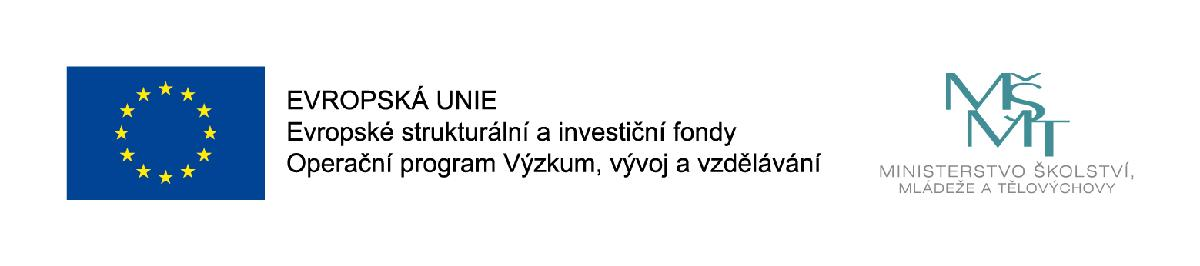

#### prof. Ing. Josef ŠTĚTINA, Ph.D. / Vysoké učení technické v Brně

#### email: [josef.stetina@vutbr.cz](mailto:josef.stetina@vutbr.cz)

#### www: [http://termomechanika.online/](http://termomechanika.online/)

#### www: [http://bit.ly/termomechanika_online/](http://bit.ly/termomechanika_online/)

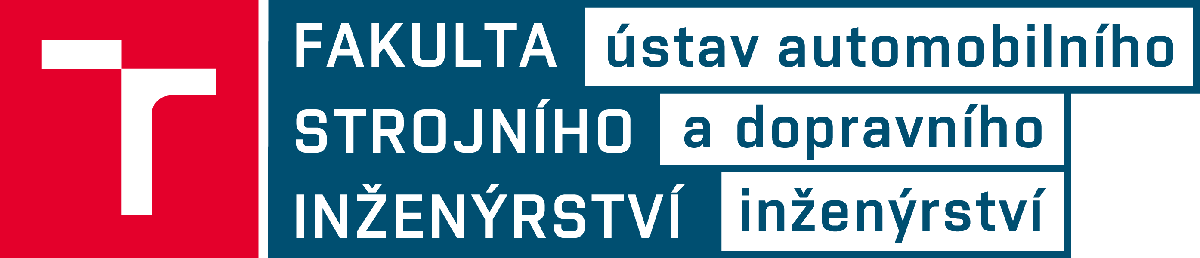

Vlhký vzduch je typickým představitelem směsi plynů a par. Jeho studiem lze získat představu, jak se chovají směsi plynů a par vzájemně chemicky netečných při různých dějích. Ačkoliv v technické praxi je mnoho soustav, které používají směsi tvořené ideálními plyny a parou, zaměříme se na směs suchého vzduchu a vodní páry, nazývanou vlhký vzduch. Takovou směsí je atmosférický vzduch, který nás obklopuje a který je pracovní látkou v řadě zařízení. Zvláštností směsi plynů a par je, že jedna její složka, a to pára může kondenzovat. 

Pro zjednodušení fyzikálního popisu vlhkého vzduchu, s nímž se setkáváme v přírodě nebo v technických procesech, se omezujeme pouze na uvedené dvě složky (suchý vzduch a voda) a neuvažujeme přítomnost dalších látek – různé plynné, kapalné nebo tuhé příměsi či znečišťující látky.

**Suchý vzduch** je směsí inertních plynů. Při běžných atmosférických podmínkách se svými vlastnostmi blíží chování ideálního plynu, resp. nedokonalého plynu, poněvadž měrné tepelné kapacity se s teplotou mění. Avšak v rozmezí teplot (-30 až 100) °C považujeme měrné tepelné kapacity za konstantní. 

**Voda a vodní pára. **Stavové rovnice vody a vodní páry jsou podstatně vzdáleny stavové rovnici ideálního plynu. V atmosférickém vzduchu za běžných podmínek však má parciální tlak vodní páry nízké hodnoty (do 1 kPa) a za těchto podmínek se vodní pára obsažená ve vlhkém vzduchu svými vlastnostmi blíží chování ideálnímu plynu. 

**Vlhký vzduch**. Ve vlhkém vzduchu, který obsahuje přehřátou vodní páru, je parciální tlak vodních par ve směsi nižší než syté vodní páry při dané teplotě vzduchu a vzduch je **nenasycený** vlhkostí. Jestliže parciální tlak vodní páry ve vzduchu dosáhne hodnoty tlaku syté páry *p**p**´´ *při dané teplotě vzduchu, dostáváme vzduch **nasycený** vlhkostí, který obsahuje suchý vzduch a sytou vodní párou. Hodnotou parciálního tlaku sytých par *p**p**´´*je určeno množství vlhkosti, které je vzduch při dané teplotě schopen pojmout ve formě páry. V nasyceném vlhkém vzduchu je tedy obsaženo maximální možné množství vodní páry. V obou těchto případech je vlhký vzduch (nenasycený i nasycený) homogenní směsí, analogickou směsi plynů.

**Rozlišujeme vzduch:**

- nenasycený vlhkostí - s párou H2O

- nasycený vlhkostí - se sytou párou H2O

- přesycený vlhkostí - se sytou párou H2O a navíc:  

-         mlhou ve formě kapiček při *t* > 0 °C 

-         ledovou mlhou ve formě krystalků při *t *< 0 °C 

-         kapičkami i ledovou mlhou při *t* = 0 °C

### **VYJÁDŘENÍ VLHKOSTI VZDUCHU**


$$$\phi  = {\kern 1pt} \frac{{{\rho _p}}}{{\rho _p^}}{\kern 1pt}  = {\kern 1pt} \frac{{{{{p_p}} \mathord{\left/
 {{{{p_p}} {{r_p}T}}} \right.
 \kern-\nulldelimiterspace} {{r_p}T}}}}{{{{p_p^} \mathord{\left/
 {{{p_p^} {{r_p}T}}} \right.
 \kern-\nulldelimiterspace} {{r_p}T}}}}{\kern 1pt}  = {\kern 1pt} \frac{{{p_p}}}{{p_p^}}$$$


% Konstanty
VV_Rv = 287.11;
VV_Cpv=1.01;
VV_Ttr=0.01;
VV_T12a=-0.00000009929086464;
VV_T12b=0.010060646;
VV_L23=2500;
VV_L12=-332;
VV_Rp=461.5;
VV_Cpp=1.84;
VV_Ck=4.187;
VV_Ct=2.09;

### Příklad

V místnosti je vzduch o teplotě 10 °C a vlhkoměr ukazuje 85 % relativní vlhkosti při barometrickém tlaku 100 kPa. Určete: 

1. Jak se změní relativní vlhkost vzduchu, zvýší-li se teplota na 15 °C

2. Jak se změní relativní vlhkost vzduchu, klesne-li teplota na 5 °C

t1 = 10;
phi1 = 0.85;
pbar = 100;   
t2 = 15;
t3 = 5;
%
pps1=pwsp80(t1);
pps2=pwsp80(t2);
pps3=pwsp80(t3);
t = tr(t1,phi1);
x1 = 0.622*phi1*pps1/(pbar*1000-phi1*pps1);
phi2 = x1*pbar*1000/(x1*pps2+0.622*pps2);
phi3 = x1*pbar*1000/(x1*pps3+0.622*pps3);


Výpočet parciálního tlaku syté vodní páry pro teploty 0 až 80 °C

function [pps] = pwsp80(t)
  pps = exp(23.58-4044.2/(235.6+t));
end

Výpočet parciálního tlaku syté vodní páry pro teploty -20 až 0 °C

function [pps] = pwsp0(t)
  pps = exp(28.926-6148.0/(273.15+t));
end

Funkce výpočtu trojného bodu

function [t] = tr(t,phi)
  a = log(phi*exp((17.67*t)/(243.5+t)));
  t = (243.5 * a) / (17.67 - a);
end

function [p_subl] = p_sytych_par_subl_ASHRAE(teplota)
  C1=-5.6745359*10^3;
  C2=-5.1523058*10^-1;
  C3=-9.6778430*10^-3;
  C4=6.2215701*10^-7;
  C5=2.0747825*10^-9;
  C6=-9.4840240*10^-13;
  C7=4.1635019*10^0;
  T=teplota+273.15;
  p_subl =1000*Exp(C1/T+C2*T^0+C3*T^1+C4*T^2+C5*T^3+C6*T^4+C7*log(T));
end